# Proyecto PRIME

clear; close all; format compact

## 1. Implementación de todos los modos de comunicación de PRIME en el caso de canal sin distorsión y sin FEC (4pts)

#### 1. Elección de parámetros de simulación

    El número de símbolos OFDM por trama se establece para que el canal en caso de ser dispersivo sea estable durante 100 ms. En la página 13 de la ITU-T G.9904 se especifica que la duración del payload para M símbolos OFDM debe ser M*2.24ms. La duración de un símbolo OFDM debe ser 2.24ms. 

    * *Asumimos que el tiempo de estabilidad de 100ms se aplica a la trama completa (preamble+header+payload)*

% T_pre = 2.048 % Duracion del preamble (ms)
tSym = 2.24; % Durancion de un símbolo OFDM (ms)
tTotal = 100; % Duración de una trama OFDM (ms)
Nofdm = floor((tTotal)/tSym); % Número de símbolos OFDM por trama

    En la página 16 de la ITU-T G.9904 indica que se deben usar 96 portadoras de datos

nPay = 96; % Número de tramas payload

    El número de bits se establece para obtener valores de BER fiables, inferiores a 10-4. Este número debe ser mayor de 10000. 

mcm = log2(2)*log2(4)*log2(8); % MCM
nBits = nPay*Nofdm*mcm; % Número de bits

#### 2. Mostrar que el comportamiento del sistema simulado corresponde con el teórico en términos de curvas de BER frente a SNR, para todos los modos de comunicación sin FEC definidos en el estándar. SNR es la relación señal a ruido a la entrada del receptor sobre el ancho de banda útil de la señal OFDM, las frecuencias para las que las portadoras no son nulas, para un canal AWGN invariante en frecuencia, es decir, considerando que la respuesta impulsiva de canal es h[n] = [1]. 

Mostrar que, en ausencia de ruido, y sin incluir prefijo cíclico, la transmisión recepción, empleando en la cadena de transmisión únicamente modulador DPSK + IFFT, y en la de recepción FFT + demodulador DPSK, no genera ningún error. 

% Vector de bits a transmitir
txBits = round(rand(1,nBits));

El tamaño de la NFFT es de 512 muestras.

% Variables
NFFT = 512;

Se realiza la IFFT de las señales moduladas.

% Modulación DNPSK de los bits aleatorizados
x.dbpsk = modDNPSK(txBits,2,NFFT,Nofdm,0);
x.dqpsk = modDNPSK(txBits,4,NFFT,Nofdm,0);
x.d8psk = modDNPSK(txBits,8,NFFT,Nofdm,0);

% Demodulación DNPSK
rxBits.dbpsk = demodDNPSK(x.dbpsk,2,NFFT,Nofdm,0);
rxBits.dqpsk = demodDNPSK(x.dqpsk,4,NFFT,Nofdm,0);
rxBits.d8psk = demodDNPSK(x.d8psk,8,NFFT,Nofdm,0);

Mostrar la ausencia de errores de transmisión cuando se añade a la cadena del punto anterior los bloques de aleatorización y desaleatorización. 

% Error en la transmisión DBPSK
error.dbpsk = sum(rxBits.dbpsk-txBits);
disp("El error de transmisión en DBPSK es: " + error.dbpsk)

El error de transmisión en DBPSK es: 0


% Error en la transmisión DQPSK
error.dqpsk = sum(rxBits.dqpsk-txBits);
disp("El error de transmisión en DQPSK es: " + error.dqpsk)

El error de transmisión en DQPSK es: 0


% Error en la transmisión D8PSK
error.d8psk = sum(rxBits.d8psk-txBits);
disp("El error de transmisión en D8PSK es: " + error.d8psk)

El error de transmisión en D8PSK es: 0


#### **3. Mostrar la ausencia de errores de transmisión cuando se añade a la cadena del punto anterior los bloques de aleatorización y desaleatorización. **

Aleatorización de la secuencia de bits.

% Aleatorización
randomizedBits = scrambler(txBits);

Modulación y Demodulación. 

% Modulación DNPSK de los bits aleatorizados
x.dbpsk = modDNPSK(randomizedBits,2,NFFT,Nofdm,0);
x.dqpsk = modDNPSK(randomizedBits,4,NFFT,Nofdm,0);
x.d8psk = modDNPSK(randomizedBits,8,NFFT,Nofdm,0);

% Demodulación DNPSK
rxBits.dbpsk = demodDNPSK(x.dbpsk,2,NFFT,Nofdm,0);
rxBits.dqpsk = demodDNPSK(x.dqpsk,4,NFFT,Nofdm,0);
rxBits.d8psk = demodDNPSK(x.d8psk,8,NFFT,Nofdm,0);

Desaleatorización.

% Aleatorización DBPSK
unrandomizedBits.dbpsk = scrambler(rxBits.dbpsk);
% Aleatorización DQPSK
unrandomizedBits.dqpsk = scrambler(rxBits.dqpsk);
% Aleatorización D8PSK
unrandomizedBits.d8psk = scrambler(rxBits.d8psk);

Se comprueba cuantos bits han resultado erróneos.

% Error en la transmisión DBPSK aleatorizada
error.dbpsk = sum(abs(unrandomizedBits.dbpsk-txBits));
disp("El error de transmisión en DBPSK es: " + error.dbpsk)

El error de transmisión en DBPSK es: 0


% Error en la transmisión DQPSK aleatorizada
error.dqpsk = sum(abs(unrandomizedBits.dqpsk-txBits));
disp("El error de transmisión en DQPSK es: " + error.dqpsk)

El error de transmisión en DQPSK es: 0


% Error en la transmisión D8PSK aleatorizada
error.d8psk = sum(abs(unrandomizedBits.d8psk-txBits));
disp("El error de transmisión en D8PSK es: " + error.d8psk)

El error de transmisión en D8PSK es: 0


Finalmente, representar las curvas BER vs SNR teóricas y simuladas, estas últimas empleando secuencias de bits seudoaleatorias. 

% Vector SNR 
SNR_dB = 0:2:20;

La BER teórica:

% Cálculo de la BER teórica DBPSK, DQPSK y D8PSK
BER.teo.dbpsk = DBPSK_BER(SNR_dB);
BER.teo.dqpsk = DQPSK_BER(SNR_dB);
BER.teo.d8psk = D8PSK_BER(SNR_dB);

BER.teo.dbpsk(find(BER.teo.dbpsk<1e-5)) = NaN;
BER.teo.dqpsk(find(BER.teo.dqpsk<1e-5)) = NaN;
BER.teo.d8psk(find(BER.teo.d8psk<1e-5)) = NaN;

La BER simulada:

% Cálculo de la BER simulada DBPSK, DQPSK y D8PSK
BER.sim.dbpsk = simulateDNPSK_BER(SNR_dB,2,NFFT,Nofdm,nPay,nBits,[],true,false,false,false);
BER.sim.dqpsk = simulateDNPSK_BER(SNR_dB,4,NFFT,Nofdm,nPay,nBits,[],true,false,false,false);
BER.sim.d8psk = simulateDNPSK_BER(SNR_dB,8,NFFT,Nofdm,nPay,nBits,[],true,false,false,false);

Representación de las curvas de BER

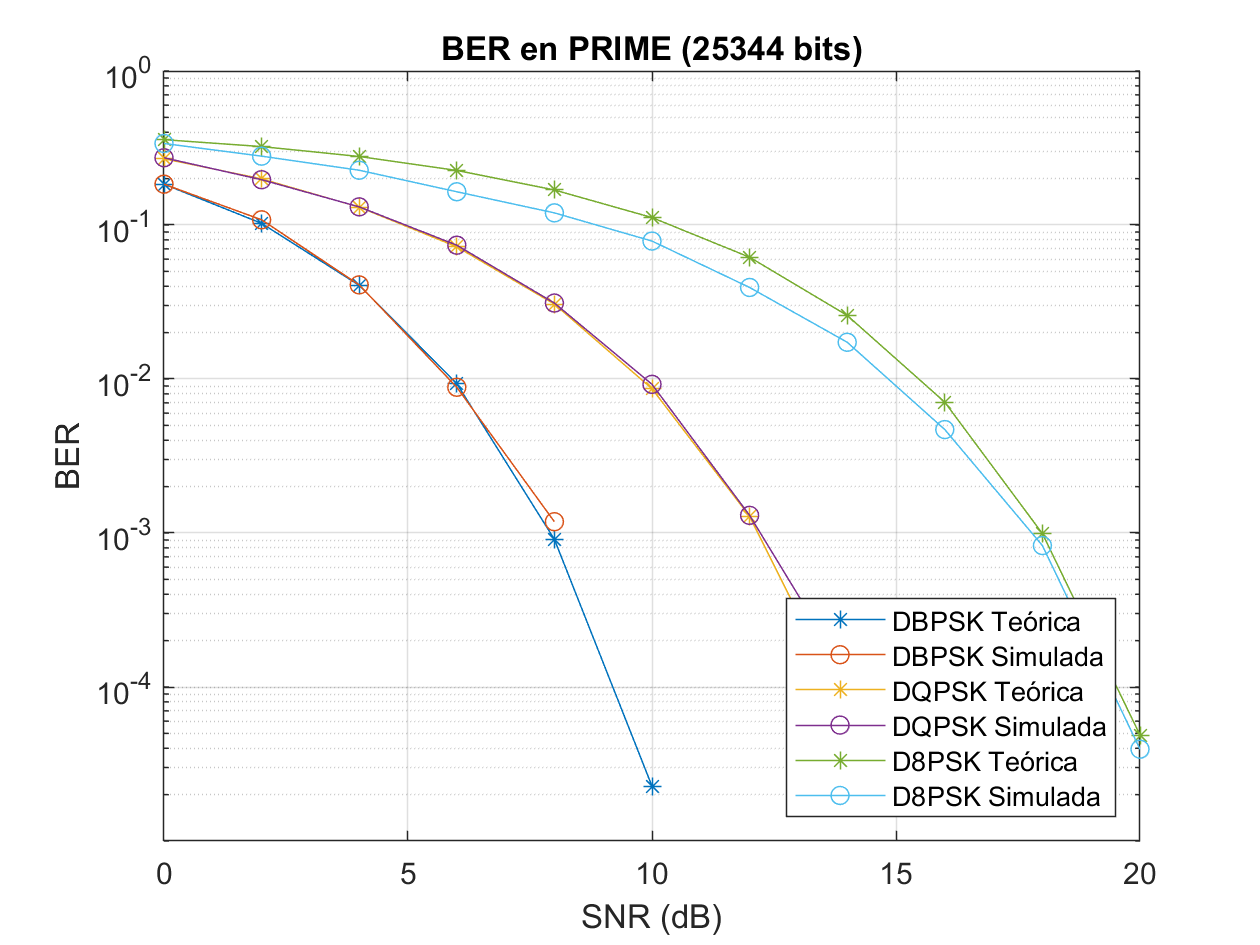

figure;
semilogy(SNR_dB, BER.teo.dbpsk, '-*');   
hold on;
semilogy(SNR_dB, BER.sim.dbpsk, '-o');
grid on;
semilogy(SNR_dB, BER.teo.dqpsk, '-*');
semilogy(SNR_dB, BER.sim.dqpsk, '-o');
semilogy(SNR_dB, BER.teo.d8psk, '-*');
semilogy(SNR_dB, BER.sim.d8psk, '-o');
xlim([SNR_dB(1) SNR_dB(end)]);
ylim([1e-5 1]);
legend('DBPSK Teórica','DBPSK Simulada','DQPSK Teórica','DQPSK Simulada','D8PSK Teórica','D8PSK Simulada',"Location","southeast");
xlabel('SNR (dB)'); 
ylabel('BER');
title(['BER en PRIME (' num2str(round(nBits,1)) ' bits)']);

Se observa que las curvas son parejas entre sí y no se encuentran significativamente distanciadas. 

##  2. Inclusiónde modelo de canal e inclusión de ecualizador (3 puntos). 

Para este apartado, se incluye un canal invariante en frecuencia. Se asume que el canal posee la siguiente repuesta al impulso discreto.

% Definicion del canal h[n]
h = [-0.1, 0.3, -0.5, 0.7, -0.9, 0.7, -0.5, 0.3, -0.1];

La expresión algebraica para la señal recibida será la convolución entre la señal y la respuesta impulsional del filtro. Un pseudocódigo para esta función:

    y[n] = Σ s[n] · h[n-k] 

Se representa la función de transferencia del canal.

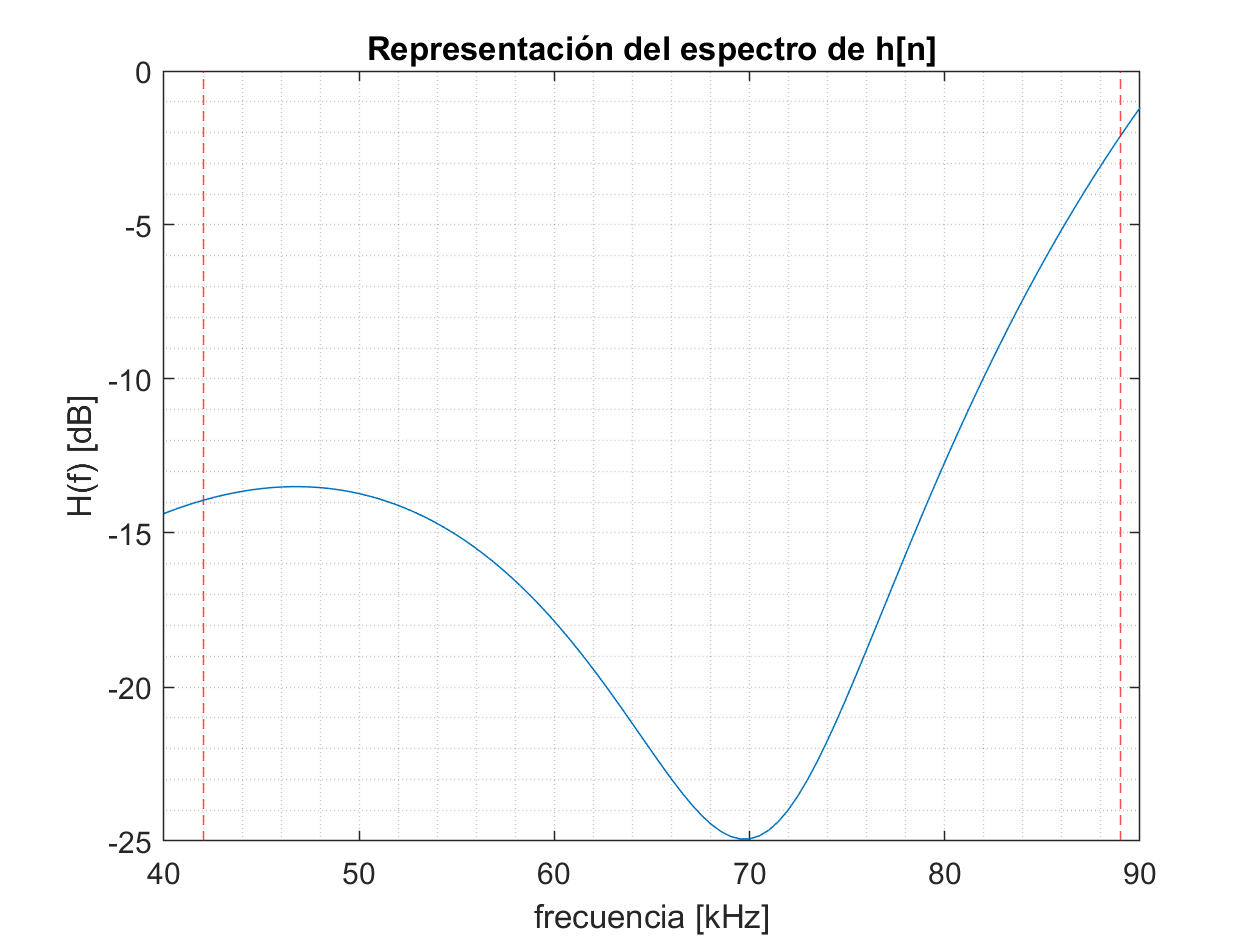

% Parametros
Nstart = 42;
Nend = 89;
df = ((Nend-Nstart)/nPay)*1000;
Fs = df*NFFT;
Ts = 1/Fs;
f = -1/(2*Ts):1/(NFFT*Ts):1/(2*Ts)-1/(NFFT*Ts);

% Espectro de h[n]
H = fft(h,NFFT);
H_dB = 20*log10(abs(H));

% Representacion del espectro h[n]
figure;
plot(f*1e-3,fftshift(H_dB));
hold on;
xline(Nstart,"r--"); % Primera portadora
xline(Nend,"r--"); % última portadora
grid minor;
xlim([40 90]);
% ylim([0 -25]);
xlabel("frecuencia [kHz]");
ylabel("H(f) [dB]");
title("Representación del espectro de h[n]");

Ahora se incluye el efecto del canal en el ejemplo de modulación y demodulación anterior (sin ecualizador ni prefijo cíclico), para obtener las curvas de BER.

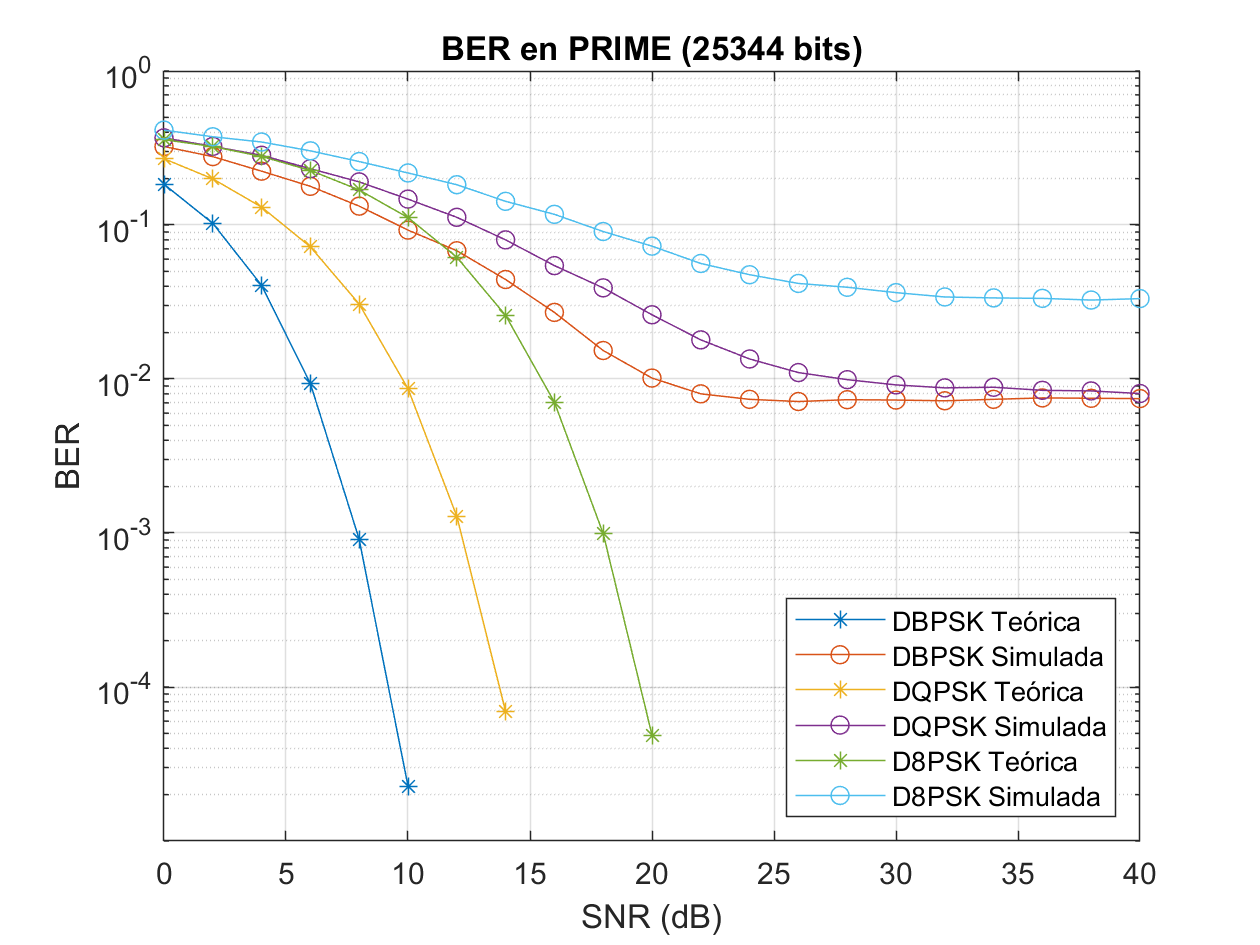

% Vector SNR 
SNR_dB = 0:2:40;

% Cálculo de la BER teórica DBPSK, DQPSK y D8PSK
BER.teo.dbpsk = DBPSK_BER(SNR_dB);
BER.teo.dqpsk = DQPSK_BER(SNR_dB);
BER.teo.d8psk = D8PSK_BER(SNR_dB);

BER.teo.dbpsk(find(BER.teo.dbpsk<1e-5)) = NaN;
BER.teo.dqpsk(find(BER.teo.dqpsk<1e-5)) = NaN;
BER.teo.d8psk(find(BER.teo.d8psk<1e-5)) = NaN;

% Cálculo de la BER simulada DBPSK, DQPSK y D8PSK
BER.sim.dbpsk = simulateDNPSK_BER(SNR_dB,2,NFFT,Nofdm,nPay,nBits,h,true,false,false,false);
BER.sim.dqpsk = simulateDNPSK_BER(SNR_dB,4,NFFT,Nofdm,nPay,nBits,h,true,false,false,false);
BER.sim.d8psk = simulateDNPSK_BER(SNR_dB,8,NFFT,Nofdm,nPay,nBits,h,true,false,false,false);

figure;
semilogy(SNR_dB, BER.teo.dbpsk, '-*');   
hold on;
semilogy(SNR_dB, BER.sim.dbpsk, '-o');
grid on;
semilogy(SNR_dB, BER.teo.dqpsk, '-*');
semilogy(SNR_dB, BER.sim.dqpsk, '-o');
semilogy(SNR_dB, BER.teo.d8psk, '-*');
semilogy(SNR_dB, BER.sim.d8psk, '-o');
xlim([SNR_dB(1) SNR_dB(end)]);
ylim([1e-5 1]);
legend('DBPSK Teórica','DBPSK Simulada','DQPSK Teórica','DQPSK Simulada','D8PSK Teórica','D8PSK Simulada',"Location","southeast")
xlabel('SNR (dB)'); 
ylabel('BER');
title(['BER en PRIME (' num2str(round(nBits,1)) ' bits)']);

Se observa como al introducir el efecto del canal aparece un fondo de BER del 1% para DBPSK y DQPSK, y del 2% para D8PSK. La distorsión que produce el canal provoca que aumente la tasa de error en la demodulación de los símbolos a su llegada. 

Se incluye ahora prefijo cíclico en el sistema, así como un ecualizador después del bloque FFT del demodulador.

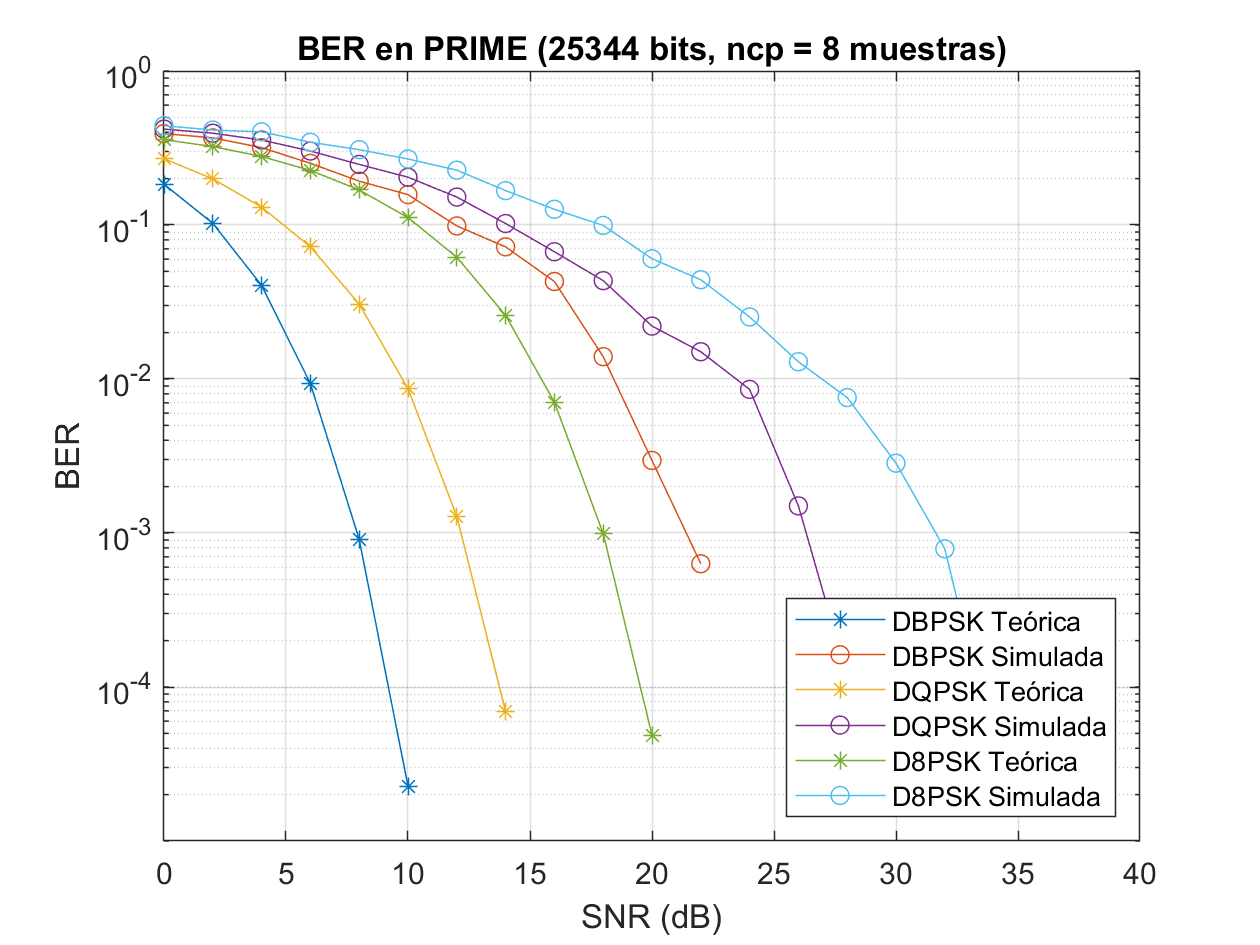

% Longitud optima del prefijo ciclico
ncp = length(h) - 1;

% Cálculo de la BER simulada DBPSK, DQPSK y D8PSK con prefijo cíclico y ecualizador
BER.sim.dbpsk = simulateDNPSK_BER(SNR_dB,2,NFFT,Nofdm,nPay,nBits,h,true,true,false,false);
BER.sim.dqpsk = simulateDNPSK_BER(SNR_dB,4,NFFT,Nofdm,nPay,nBits,h,true,true,false,false);
BER.sim.d8psk = simulateDNPSK_BER(SNR_dB,8,NFFT,Nofdm,nPay,nBits,h,true,true,false,false);

figure;
semilogy(SNR_dB, BER.teo.dbpsk, '-*');   
hold on;
semilogy(SNR_dB, BER.sim.dbpsk, '-o');
grid on;
semilogy(SNR_dB, BER.teo.dqpsk, '-*');
semilogy(SNR_dB, BER.sim.dqpsk, '-o');
semilogy(SNR_dB, BER.teo.d8psk, '-*');
semilogy(SNR_dB, BER.sim.d8psk, '-o');
xlim([SNR_dB(1) SNR_dB(end)]);
ylim([1e-5 1]);
legend('DBPSK Teórica','DBPSK Simulada','DQPSK Teórica','DQPSK Simulada','D8PSK Teórica','D8PSK Simulada',"Location","southeast");
xlabel('SNR (dB)'); 
ylabel('BER');
title(['BER en PRIME (' num2str(round(nBits,1))  ' bits, ncp = ' num2str(round(length(h)-1,1)) ' muestras)']);

La inclusión del ecualizador y el uso de un prefijo cíclico óptimo elimina el efecto de fondo de BER anteriormente presente. Sin embargo, la tasa de error simulada con respecto a la teórica se encuentra distanciadas unos 14 dB para BER inferiores a 0.1%. Esto quiere decir que, para obtener la misma BER se necesitan aproximadamente 14 dB más de SNR, en comparación con la tasa de error teórica. 

## 3. Implementación de todos los modos de comunicación de PRIME con FEC. 

El siguiente paso consiste en desarrollar e implementar las técnicas de corrección de errores o FEC definidas en el estándar.

**4. Modificación de parámetros de simulación**

Como el ratio de codificación es 1/2 se transmite la mitad de información en un mismo intervalo de tiempo. Esto quiere decir que anteriormente se transmitían 96 símbolos de información por portadora ahora se transmiten la mitad, 48. 

De acuerdo con el estándar PRIME se incluyen 8 bits de *flushing* para cada trama. Son bits que se ponen a cero. Estos valores se utilizan para los módulos de codificación y decodificación convolucional. 

Para la codificación y decodificación de códigos convolucionales se utilizan trellis para generar convolucionadores de codigo a partir de polinomios. La longitud del filtro es 7 atendiendo a las indicaciones del estándar. Los valores de estos códigos son 1111001 y 1011011. 

Por otro lado, el entrelazado facilita la corrección de errores en situaciones de error* bursting*, ya que la información se encuentra reordenada de forma que no sigue el orden original de transmisión. Para cambiar de orden los bits se ha seguido las tablas del apéndice II del estándar.

**5. Modificación de parámetros de simulación**

En ausencia de ruido, la cadena de transmisión-recepción con el nuevo módulo de entrelazado y desentrelazado no genera ningún error.

% Cálculo de la BER simulada DBPSK, DQPSK y D8PSK con entrelazado
error.dbpsk = simulateDNPSK_BER([1],2,NFFT,Nofdm,nPay,nBits,h,false,true,true,false);
error.dqpsk = simulateDNPSK_BER([1],4,NFFT,Nofdm,nPay,nBits,h,false,true,true,false);
error.d8psk = simulateDNPSK_BER([1],8,NFFT,Nofdm,nPay,nBits,h,false,true,true,false);

% Error en la transmisión DBPSK con entrelazado
disp("El error de transmisión en DBPSK con entrelazado y sin ruido es: " + error.dbpsk)

El error de transmisión en DBPSK con entrelazado y sin ruido es: 0


% Error en la transmisión DQPSK con entrelazado
disp("El error de transmisión en DQPSK con entrelazado y sin ruido es: " + error.dqpsk)

El error de transmisión en DQPSK con entrelazado y sin ruido es: 0


% Error en la transmisión D8PSK con entrelazado
disp("El error de transmisión en D8PSK con entrelazado y sin ruido es: " + error.d8psk)

El error de transmisión en D8PSK con entrelazado y sin ruido es: 0


Del mismo modo, en ausencia de ruido, si introducimos los códigos convolucionales el error sigue siendo cero. 

% Cálculo de la BER simulada DBPSK, DQPSK y D8PSK con entrelazado, códigos convolucionales y sin ruido
error.dbpsk = simulateDNPSK_BER([1],2,NFFT,Nofdm,nPay,nBits,h,false,true,true,true);
error.dqpsk = simulateDNPSK_BER([1],4,NFFT,Nofdm,nPay,nBits,h,false,true,true,true);
error.d8psk = simulateDNPSK_BER([1],8,NFFT,Nofdm,nPay,nBits,h,false,true,true,true);

% Error en la transmisión DBPSK con entrelazado, códigos convolucionales y sin ruido
disp("El error de transmisión en DBPSK con interleaver, códigos convolucionales y sin ruido es: " + error.dbpsk)

El error de transmisión en DBPSK con interleaver, códigos convolucionales y sin ruido es: 0


% Error en la transmisión DQPSK con entrelazado, códigos convolucionales y sin ruido
disp("El error de transmisión en DQPSK con interleaver, códigos convolucionales y sin ruido es: " + error.dqpsk)

El error de transmisión en DQPSK con interleaver, códigos convolucionales y sin ruido es: 0


% Error en la transmisión D8PSK con entrelazado, códigos convolucionales y sin ruido
disp("El error de transmisión en D8PSK con interleaver, códigos convolucionales y sin ruido es: " + error.d8psk)

El error de transmisión en D8PSK con interleaver, códigos convolucionales y sin ruido es: 0


Ahora se añaden ruido blanco y se representan las curvas de BER. 

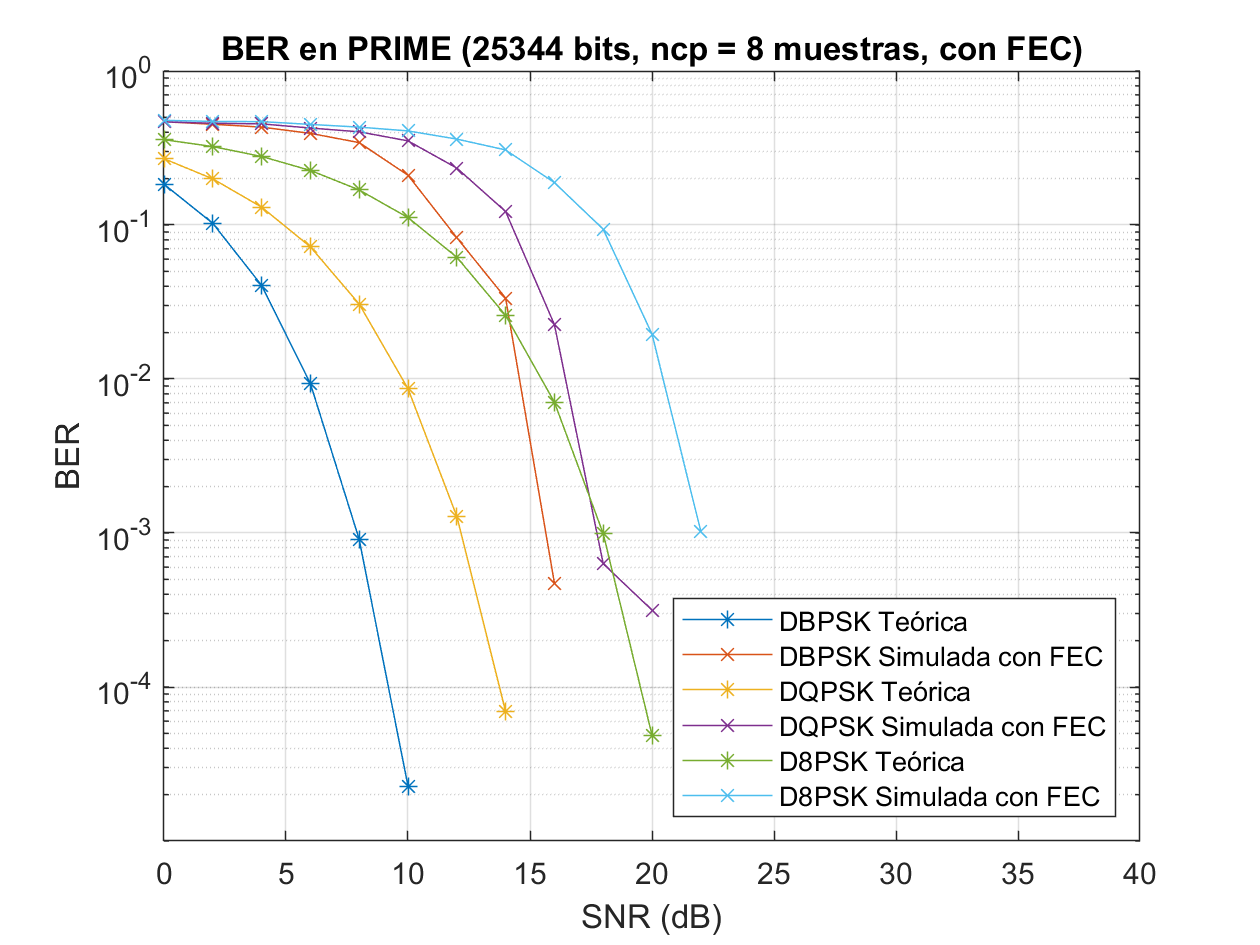

% Cálculo de la BER simulada DBPSK, DQPSK y D8PSK con interleaver
BER.FEC.sim.dbpsk = simulateDNPSK_BER(SNR_dB,2,NFFT,Nofdm,nPay,nBits,h,true,true,true,true);
BER.FEC.sim.dqpsk = simulateDNPSK_BER(SNR_dB,4,NFFT,Nofdm,nPay,nBits,h,true,true,true,true);
BER.FEC.sim.d8psk = simulateDNPSK_BER(SNR_dB,8,NFFT,Nofdm,nPay,nBits,h,true,true,true,true);

figure;
semilogy(SNR_dB, BER.teo.dbpsk, '-*');   
hold on;
grid on;
semilogy(SNR_dB, BER.FEC.sim.dbpsk, '-x');
semilogy(SNR_dB, BER.teo.dqpsk, '-*');
semilogy(SNR_dB, BER.FEC.sim.dqpsk, '-x');
semilogy(SNR_dB, BER.teo.d8psk, '-*');
semilogy(SNR_dB, BER.FEC.sim.d8psk, '-x');
xlim([SNR_dB(1) SNR_dB(end)]);
ylim([1e-5 1]);
legend('DBPSK Teórica','DBPSK Simulada con FEC','DQPSK Teórica','DQPSK Simulada con FEC','D8PSK Teórica','D8PSK Simulada con FEC',"Location","southeast");
xlabel('SNR (dB)'); 
ylabel('BER');
title(['BER en PRIME (' num2str(round(nBits,1))  ' bits, ncp = ' num2str(round(length(h)-1,1)) ' muestras, con FEC)']);

Finalmente se realiza una comparación de las curvas de BER con y sin FEC.

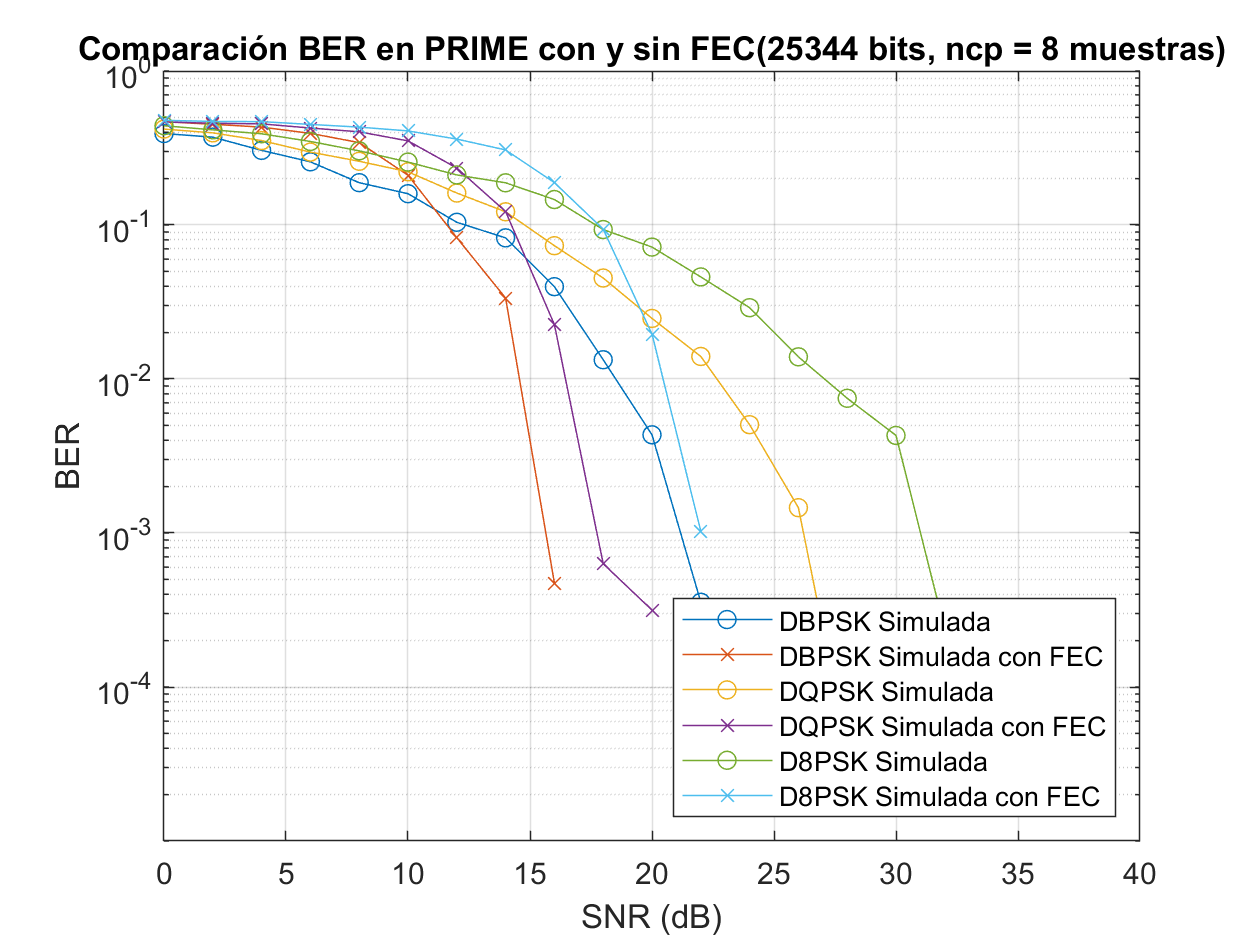

% Cálculo de la BER simulada DBPSK, DQPSK y D8PSK con interleaver
BER.sim.dbpsk = simulateDNPSK_BER(SNR_dB,2,NFFT,Nofdm,nPay,nBits,h,true,true,false,false);
BER.sim.dqpsk = simulateDNPSK_BER(SNR_dB,4,NFFT,Nofdm,nPay,nBits,h,true,true,false,false);
BER.sim.d8psk = simulateDNPSK_BER(SNR_dB,8,NFFT,Nofdm,nPay,nBits,h,true,true,false,false);

figure;  
semilogy(SNR_dB, BER.sim.dbpsk, '-o');
hold on;
grid on;
semilogy(SNR_dB, BER.FEC.sim.dbpsk, '-x');
semilogy(SNR_dB, BER.sim.dqpsk, '-o');
semilogy(SNR_dB, BER.FEC.sim.dqpsk, '-x');
semilogy(SNR_dB, BER.sim.d8psk, '-o');
semilogy(SNR_dB, BER.FEC.sim.d8psk, '-x');
xlim([SNR_dB(1) SNR_dB(end)]);
ylim([1e-5 1]);
legend('DBPSK Simulada','DBPSK Simulada con FEC','DQPSK Simulada','DQPSK Simulada con FEC','D8PSK Simulada','D8PSK Simulada con FEC',"Location","southeast");
xlabel('SNR (dB)'); 
ylabel('BER');
title(['Comparación BER en PRIME con y sin FEC(' num2str(round(nBits,1))  ' bits, ncp = ' num2str(round(length(h)-1,1)) ' muestras)']);

Para tasas de error de bit inferiores a 0.1%, la utilización de FEC supone una diferencia de 6dB en cuanto a la relación señal a ruido necesaria para el caso de DBPSK. Esto implica que si utilzamos esta técnica de corrección de errores podemos obtener la misma tasa de error de bit que si no lo utilizasemos con una SNR 6dB menor. 

Para el caso de DQPSK, esta diferencia es de aproximadamente 8dB. 

Por último, en D8PSK la diferencia se estima en 9dB.

De esta forma queda demostrado la efectividad de emplear FEC mediante códigos convolucionales y técnicas de entralazado, permitiendo obtener un mejor rendimiento del sistema PRIME.  